% Assuming your data is in a table 'train_data' with columns 'time', 'hmd', 'spd', 'tmp', 'pm2d5', 'lat', 'lon'

% Create a new column 'time_numeric' to hold the numerical time feature
train_data.time_numeric = hour(train_data.time) + minute(train_data.time)/60;

% Randomly sample 10,000 rows for training and 2,000 for validation
rng(0); % Seed for reproducibility
total_rows = height(train_data);
indices = randperm(total_rows, 12000);
train_indices = indices(1:10000);
validation_indices = indices(10001:end);

% Split the data
train_data_subset = train_data(train_indices, :);
validation_data_subset = train_data(validation_indices, :);

% Extract features and response for training
X_train = train_data_subset{:, {'time_numeric', 'hmd', 'spd', 'tmp', 'lat', 'lon'}};
y_train = train_data_subset.pm2d5;

% Extract features and response for validation
X_validation = validation_data_subset{:, {'time_numeric', 'hmd', 'spd', 'tmp', 'lat', 'lon'}};
y_validation = validation_data_subset.pm2d5;

% Scale the features, since SVMs are sensitive to the scaling of the data
% Use zscore for scaling
%X_train_scaled = zscore(X_train);
%X_validation_scaled = zscore(X_validation);

% Train the SVM regression model on the training data
SVMModel = fitrsvm(X_train, y_train, 'Standardize', true, 'KernelFunction', 'rbf');

% Validate the model on the validation data
predicted_pm2d5_validation = predict(SVMModel, X_validation);


% Here you can compute validation metrics (e.g., RMSE, MAE) using predicted_pm2d5_validation and y_validation
% Assuming that predicted_pm2d5_validation and y_validation are already defined

% Calculate RMSE
rmse = sqrt(mean((predicted_pm2d5_validation - y_validation).^2));

% Calculate the normalizing term
normalizing_term = sqrt(mean(y_validation.^2));

% Calculate NRMSE
nrmse = rmse / normalizing_term;

% Display NRMSE
fprintf('The NRMSE of the SVM model is: %.3f\n', nrmse);

The NRMSE of the SVM model is: 0.256


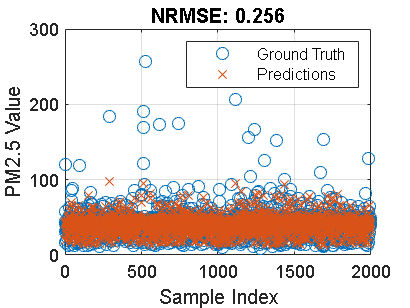


% Plot the predicted values against the ground truth values
figure; % Create a new figure
plot(y_validation, 'o', 'DisplayName', 'Ground Truth'); % Plot ground truth as circles
hold on; % Hold on to the current figure
plot(predicted_pm2d5_validation, 'x', 'DisplayName', 'Predictions'); % Plot predictions as crosses
hold off; % Release the figure

% Label the plot
xlabel('Sample Index');
ylabel('PM2.5 Value');
title(sprintf('NRMSE: %.3f', nrmse));
legend('show'); % Show legend

% Display the plot
grid on; % Add a grid for better readability

% Assuming 'SVMModel' is your trained model and 'test_data' and 'soln_data' are your test datasets

% Add a numeric time column to test_data
test_data.time_numeric = hour(test_data.time) + minute(test_data.time) / 60;

% Scale the test features, excluding the original time column
% Now including the 'time_numeric' column
test_features = test_data{:, {'time_numeric', 'hmd', 'spd', 'tmp', 'lat', 'lot'}};

% Predict PM2.5 values using the scaled features
pred_pm2d5 = predict(SVMModel, test_features);

% Extract the true PM2.5 values from soln_data
true_pm2d5 = soln_data; % assuming the true PM2.5 values are the only column in soln_data

% Calculate the NRMSE
rmse = sqrt(mean((pred_pm2d5 - true_pm2d5).^2));
normalizing_term = sqrt(mean(true_pm2d5.^2));
nrmse = rmse / normalizing_term;

% Display the NRMSE
fprintf('The NRMSE of the SVM model on the test set is: %.3f\n', nrmse);

The NRMSE of the SVM model on the test set is: 1.007


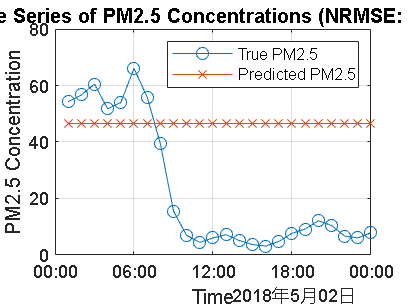


% Plot the time series using the original time for the x-axis
figure;
plot(test_data.time, true_pm2d5, 'o-', 'DisplayName', 'True PM2.5');
hold on;
plot(test_data.time, pred_pm2d5, 'x-', 'DisplayName', 'Predicted PM2.5');
hold off;
xlabel('Time');
ylabel('PM2.5 Concentration');
title(sprintf('Time Series of PM2.5 Concentrations (NRMSE: %.3f)', nrmse));
legend('show');
grid on;